# Predict Air Quality on Current Data (Calling Python from MATLAB)

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model. Ultimately these will both be integrated into a web application

Setup information, version info, and more on integrating MATLAB and Python can be found here:

[https://www.mathworks.com/help/matlab/getting-started-with-python.html](https://www.mathworks.com/help/matlab/getting-started-with-python.html)

Check that MATLAB can recognize the Python installation. You can also provide name- value pairs to specify version, path to the desired python executable, and additional info.  (Use `pyversion` if using a MATLAB release before R2019b) 

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.6"
       Executable: "C:\Python36\WPy-3670\python-3.6.7.amd64\python.EXE"
          Library: "C:\Python36\WPy-3670\python-3.6.7.amd64\python36.dll"
             Home: "C:\Python36\WPy-3670\python-3.6.7.amd64"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "2208"
      ProcessName: "MATLABPyHost"

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

## Read weather data using Python module 

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

You may need to set the Python path (if you haven't done this through environment settings) The code must be accessible by both paths. The Python path can be set using the following for example. 

% pathToFile = fileparts(which('weather.py'));
% if count(py.sys.path,pathToFile) == 0
%     insert(py.sys.path,int32(0),pathToFile);
% end

Use the `weather.py` module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Boston","US",apikey.Key(1))

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.06, 'lat': 42.36}, 'weather': [{'id': 802, 'main': 'Clouds', 'description': 'scattered clouds', 'icon': '03d'}], 'base': 'stations', 'main': {'temp': 68.9, 'feels_like': 61.09, 'temp_min': 66.99, 'temp_max': 71.01, 'pressure': 1018, 'humidity': 46}, 'visibility': 10000, 'wind': {'speed': 12.75, 'deg': 190}, 'clouds': {'all': 40}, 'dt': 1602008942, 'sys': {'type': 1, 'id': 3486, 'country': 'US', 'sunrise': 1601981232, 'sunset': 1602022616}, 'timezone': -14400, 'id': 4930956, 'name': 'Boston', 'cod': 200}

Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 68.9, 'feels_like': 61.09, 'temp_min': 66.99, 'temp_max': 71.01, 'pressure': 1018, 'humidity': 46, 'speed': 12.75, 'deg': 190, 'lon': -71.06, 'lat': 42.36, 'city': 'Boston', 'current_time': '2020-10-06 14:34:18.799698'}

## Preprocess data 

Now, we want to use the data in MATLAB to make the prediction, so we will convert it to an MATLAB appropriate data type. See [data type conversions](https://www.mathworks.com/help/matlab/python-data-types.html) for a comprehensive list. 

You can also quickly examine various conversion options and some available functionality by checking the methods. This can help decide on data types quickly, when not converted directly. 

methods(weatherData)

Methods for class py.dict:

char        dict        get         keys        ne          setdefault  values      
clear       eq          gt          le          pop         struct      
copy        ge          items       lt          popitem     update      

Static methods:

fromkeys    

Methods of py.dict inherited from handle.



The Python dictionary can be represented as a MATLAB struct. 

data = struct(weatherData)

data = struct with fields:
            temp: 68.9000
      feels_like: 61.0900
        temp_min: 66.9900
        temp_max: 71.0100
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
           speed: 12.7500
             deg: [1×1 py.int]
             lon: -71.0600
             lat: 42.3600
            city: [1×6 py.str]
    current_time: [1×26 py.str]

You can then convert the underlying data to the desired MATLAB data types. 

string(data.city)

ans = "Boston"

Use the function defined at the bottom of the script to convert remaining data

convertData(data)

ans = 1×10 table
     T        P       RH     WindSpd    WindDir        deg          lon       lat       city           DateLocal      
    ____    _____    ____    _______    _______    ____________    ______    _____    ________    ____________________
    68.9    61.09    1018      46        12.75     [1×1 py.int]    -71.06    42.36    "Boston"    06-Oct-2020 14:34:18

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

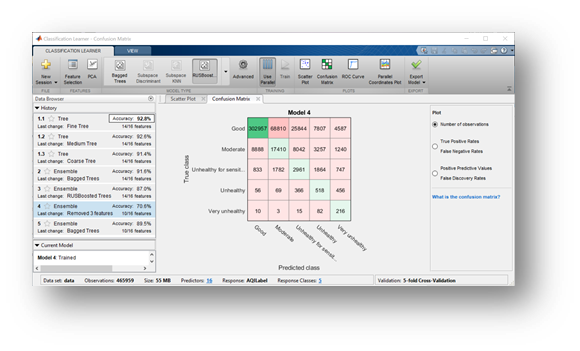

Use a function (`prepData.m`) to prepare data for machine learning based on model expectations (create a table with the expected variable names, preprocessing steps, etc). This also includes the data conversion steps shown above.

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName       T        P        DP       RH     WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    ____    _____    ______    ____    _______    _______    ____    __    __
    06-Oct-2020 14:34:18    "Boston"    Massachusetts    68.9    61.09    399.38    1018     12.75       46       2020    10    6 

Use the previously trained model to predict the air quality for the new weather data.

load airQualModel 

airQual = predict(model,currentData)

airQual = categorical
     Moderate 

## Share prediction code

Create a function with these steps to be called in the Python environment or MATLAB web app.

edit predictAirQual.m

## Use MATLAB Air Quality Model in Python

Now that we can call our Python code from MATLAB, lets call the MATLAB code from Python. This will help test the code from both languages to better anticipate the data types, conversion needs, etc. when integrating into the final web application. There are two options for calling MATLAB from Python, depending on your needs.

See `CallMATLABfromPython.ipynb` to use the [MATLAB Engine API for Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html) for the air quality prediction. You'll need to run a setup.py script included with MATLAB to make the connection. [Here's an example and additional troubleshooting info](https://uk.mathworks.com/help/matlab/matlab_external/install-the-matlab-engine-for-python.html).

The model and code can also be packaged and run without access to MATLAB using [MATLAB Compiler SDK](https://www.mathworks.com/help/compiler_sdk/python_packages.html). First, use the Library Compiler App to package the MATLAB code. 

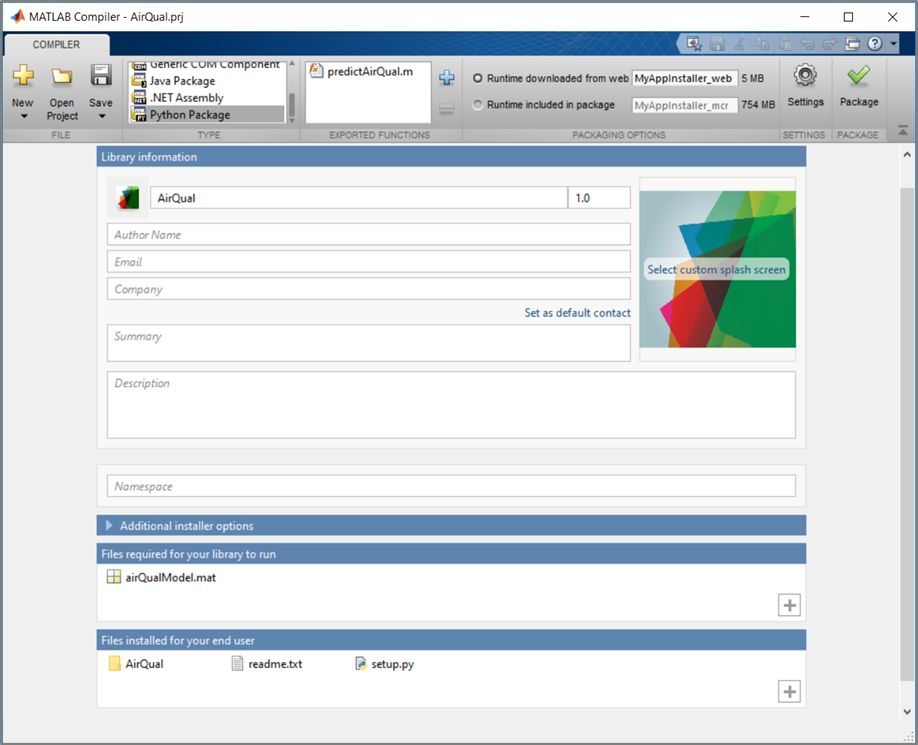

Then, to run in Python:

- Open a command prompt in the `for_redistribution_files_only` folder

- Run the setup script to install the package:  ` python setup.py install` 

See `MATLABPackageFromPython.ipynb` for calling the package from Python.

## Create web application

In this example, the goal is to create an app combining the current data import from Python and the data prep and machine learning code from MATLAB to predict current air quality for a given location.

There are two options for creating the web app in this example:

- Using MATLAB App Designer (then an app guides you through creating the web application, hosting it)

- Integrating via a RestFUL API (to be used from external dashboard, html/javascript, etc)

See `CreateWebApp.mlx` for the examples and more details.

% edit CreateWebApp.mlx

**Helper Function**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end